y=[126743 127627 128453 129227 129988 130756 131448 132129 132802 133450 134091 134735 135404 136072 136782 137462]/10000; 
y1=y;
x=1:16;
myfunc=inline('beta(1)./(1+(beta(1)/beta(2)-1).*exp(-beta(3).*x))','beta','x');
beta=nlinfit(x,y,myfunc,[2 2 2]);

k=beta(1);
a=beta(2);
r=beta(3);
x=2000:2015;
plot(x,y,'o')
hold on;
x=2000:2031;%2050年人数15.2615
yy=k./(1+(k/a-1)*exp(-r*(x-2000)))+0.08

yy =           12.6846560933135          12.7649944058837          12.8440265086261          12.9217516748262          12.9981702791327          13.0732837606329          13.1470945851375          13.2196062068197           13.290823029353          13.3607503666825            13.42939440356          13.4967621559682          13.5628614315497           13.627700790154          13.6912895046047          13.7536375217861          13.8147554241388          13.8746543916482          13.9333461644041          13.9908430058003          14.0471576664391          14.1023033487992          14.1562936727155          14.2091426417199          14.2608646102801          14.3114742519708          14.3609865286081          14.4094166603676          14.4567800969081          14.5030924895134          14.5483696642634            14.59262759624


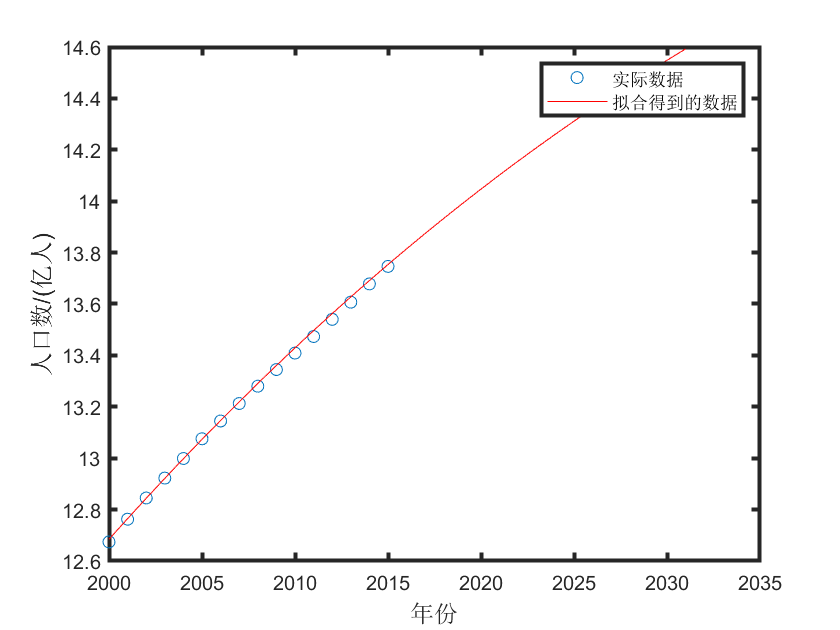

plot(x,yy,'r')
legend('实际数据','拟合得到的数据')
set(gca,  'LineWidth',2);
xlabel('年份', 'fontsize',12)
ylabel('人口数/(亿人)','fontsize',12)